clear;
addpath data\;
addpath fun\;

addpath fun\freq_domain_regre\;

Filename_h5 = "Flt1002-train.mat";
feature_cur = {"CUR_COM1","CUR_ACHi","CUR_ACLo",...
    "CUR_TANK","CUR_FLAP","CUR_STRB",...
    "CUR_SRVO_O","CUR_SRVO_M","CUR_SRVO_I",...
    "CUR_IHTR","CUR_ACPWR","CUR_OUTPWR",...
    "CUR_BAT1","CUR_BAT2","V_BLOCK"};
cur_data = [];
for i=1:length(feature_cur)
    feature = feature_cur{i};
    load(Filename_h5,feature);
    data_temp = load(Filename_h5,feature);
    data_temp = getfield(data_temp, feature);
    cur_data = [cur_data data_temp];
end
features = {...
    "LINE","TIME","IGRFMAG1","COMPMAG1","FLUXB_X","FLUXB_Y","FLUXB_Z","INS_LON","INS_LAT"};

for i=1:length(features)
    feature = features{i};
    load(Filename_h5,feature);
end
feature_tfm = {"UNCOMPMAG3","UNCOMPMAG4", "UNCOMPMAG5"};
tfm_data = [];
for i=1:length(feature_tfm)
    feature = feature_tfm{i};
    load(Filename_h5,feature);
    data_temp = load(Filename_h5,feature);
    data_temp = getfield(data_temp, feature);
    tfm_data = [tfm_data data_temp];
end

cur_vmd = [];
flight_temp = [1002.02,1002.2];
x = [];
linet = flight_temp;
for i=1:length(linet)
    line_temp = linet(i);
    x_temp = find(LINE==line_temp);
    x = [x;x_temp];
end
for i=1:size(cur_data,2)
    cur_norm = normalize(cur_data(x,i));
    [u4,~,info] = vmd(cur_norm,'NumIMF',4);
    VMD_strb = flip(u4,2)';
    cur_vmd = [cur_vmd VMD_strb(1,:)'];
end
win_train = 1:12301;
win_test = 12301:length(x);

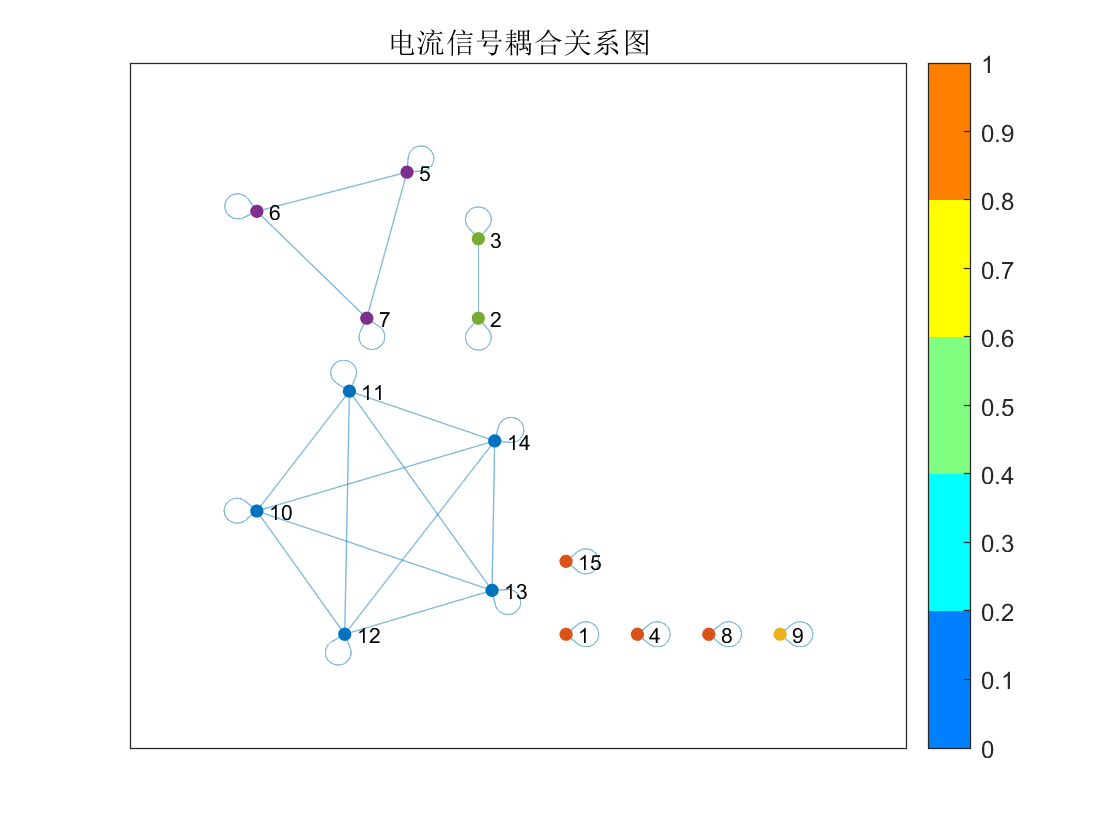

I = cur_vmd';
% 假设 I 为电流信号矩阵 (m x N)，其中 m 为电流通道数，N 为时间序列长度
[m, N] = size(I);

% 1. 计算相关性矩阵
corr_matrix = corr(I'); % 计算电流信号之间的相关性，返回 m x m 的相关性矩阵

% 2. 设置阈值，构建邻接矩阵
threshold = 0.5;  % 设定相关性阈值，低于该值的相关性将被忽略
adj_matrix = abs(corr_matrix);  % 初始邻接矩阵为相关性矩阵
adj_matrix(adj_matrix < threshold) = 0;  % 将低于阈值的相关性置为 0
adj_matrix = (adj_matrix + adj_matrix') / 2; % 保证邻接矩阵对称

% 3. 社群检测 (Louvain方法)

num_clusters = 5;  % 假设我们想分成5个簇
cluster_idx = kmeans(adj_matrix, num_clusters);  % 进行 K-means 聚类
% 为每个簇分配颜色
colors = lines(num_clusters);  % 'lines' 生成一组区分明显的颜色

% 创建一个 m x 3 的矩阵，其中每一行是对应节点的 RGB 颜色值
node_colors = colors(cluster_idx, :);
% 4. 可视化图
G = graph(adj_matrix);  % 根据邻接矩阵创建图
figure;
h = plot(G, 'NodeColor', node_colors, 'EdgeAlpha', 0.5);
% h = plot(G);
colormap(jet(num_clusters));  % 不同簇的颜色
title('电流信号耦合关系图');
colorbar; % 显示颜色条


% 显示社群分配结果
disp('社群分配结果:');

社群分配结果:


disp(cluster_idx);

     2
     5
     5
     2
     4
     4
     4
     2
     3
     1
     1
     1
     1
     1
     2




% 可选：将社群检测结果与电流信号的关系进一步分析
% 例如，找出每个社群的电流信号
for i = 1:num_clusters
    disp(['社群 ' num2str(i) ' 包含的电流通道:']);
    disp(find(cluster_idx == i));
end

社群 1 包含的电流通道:


    10
    11
    12
    13
    14



社群 2 包含的电流通道:


     1
     4
     8
    15



社群 3 包含的电流通道:


     9



社群 4 包含的电流通道:


     5
     6
     7



社群 5 包含的电流通道:


     2
     3



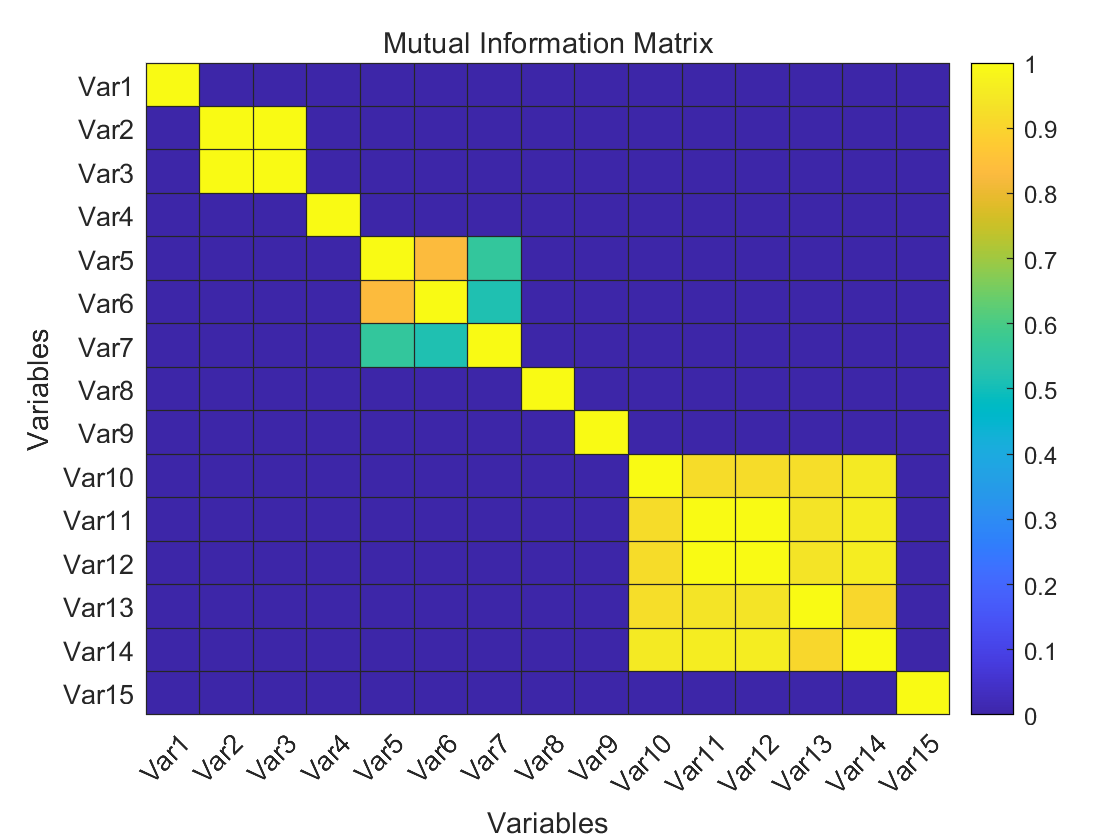

% 设置矩阵的名称
n = size(adj_matrix, 1);
variableNames = strcat("Var", string(1:n));

% 可视化互信息矩阵
figure;
heatmap(variableNames, variableNames, adj_matrix, ...
    'Colormap', parula, ...    % 使用 'parula' 配色方案
    'ColorbarVisible', 'on', ... % 显示颜色条
    'CellLabelColor', 'none'); % 隐藏单元格标签以增强视觉效果

% 设置标题和轴标签
title('Mutual Information Matrix');
xlabel('Variables');
ylabel('Variables');

% 假设 I 为电流信号矩阵 (m x N)，其中 m 为电流通道数，N 为时间序列长度
[m, N] = size(I);

% 1. 计算相关性矩阵
corr_matrix = corr(I');  % 计算电流信号之间的相关性，返回 m x m 的相关性矩阵

% 2. 使用最大化模块度确定阈值
% 尝试不同的阈值，计算每个阈值下的模块度，选择模块度最大的阈值
threshold_range = 0:0.05:1;  % 设置阈值范围
modularity_values = zeros(size(threshold_range));  % 存储每个阈值的模块度值

for i = 1:length(threshold_range)
    threshold = threshold_range(i);  % 当前阈值
    adj_matrix = abs(corr_matrix);  % 初始化邻接矩阵为相关性矩阵
    adj_matrix(adj_matrix < threshold) = 0;  % 将低于阈值的相关性置为 0
    adj_matrix = (adj_matrix + adj_matrix') / 2;  % 保证邻接矩阵对称
    
    % 使用社区检测算法（Louvain方法），假设安装了社区检测工具
    [community_labels, Q] = community_louvain(adj_matrix);  % Q是模块度
    
    modularity_values(i) = Q;  % 记录该阈值对应的模块度值
end

% 选择最大模块度对应的阈值
[~, max_modularity_idx] = max(modularity_values);
best_threshold = threshold_range(max_modularity_idx);
disp(['最佳阈值：', num2str(best_threshold)]);

最佳阈值：1


best_threshold = 0.1;
% 3. 使用最佳阈值计算邻接矩阵
adj_matrix = abs(corr_matrix);  
adj_matrix(adj_matrix < best_threshold) = 0;  
adj_matrix = (adj_matrix + adj_matrix') / 2;  

% 4. Louvain方法进行社群检测
[community_labels, Q] = community_louvain(adj_matrix);  % Q是模块度
disp(['社群数量: ', num2str(max(community_labels))]);

社群数量: 4


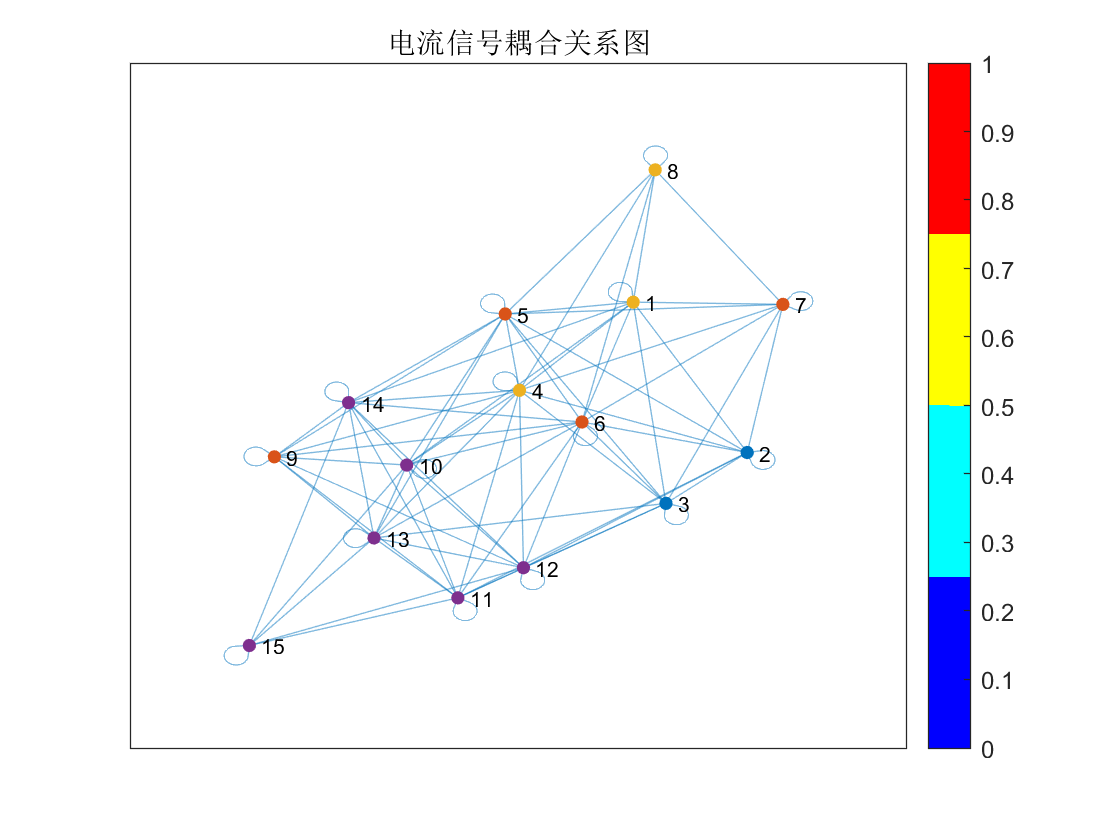


colors = lines(max(community_labels));  % 'lines' 生成一组区分明显的颜色
node_colors = colors(community_labels, :);
% 5. 可视化图
G = graph(adj_matrix);  % 根据邻接矩阵创建图
figure;
h = plot(G, 'NodeColor', node_colors, 'EdgeAlpha', 0.5);
colormap(jet(max(community_labels)));  % 不同簇的颜色
title('电流信号耦合关系图');
colorbar;  % 显示颜色条


% 显示社群分配结果
disp('社群分配结果:');

社群分配结果:


disp(community_labels);

     3
     1
     1
     3
     2
     2
     2
     3
     2
     4
     4
     4
     4
     4
     4




% 可选：将社群检测结果与电流信号的关系进一步分析
% 例如，找出每个社群的电流信号
for i = 1:max(community_labels)
    disp(['社群 ' num2str(i) ' 包含的电流通道:']);
    disp(find(community_labels == i));
end

社群 1 包含的电流通道:


     2
     3



社群 2 包含的电流通道:


     5
     6
     7
     9



社群 3 包含的电流通道:


     1
     4
     8



社群 4 包含的电流通道:


    10
    11
    12
    13
    14
    15



ICA测试

commu_1 = [2,3];
commu_2 = [1,4,8];
commu_3 = [5,6,7,9];
commu_4 = [10:15];
% 假设 I 是 m x N 的电流数据矩阵
r = 6;
[S, A, W] = fastICA(I(commu_4,win_train),r); % 使用ICA分解信号

***** Fast ICA (kurtosis) *****
Iter 001: max(1 - |<w001, w000>|) = 0.8014
Iter 002: max(1 - |<w002, w001>|) = 0.6063
Iter 003: max(1 - |<w003, w002>|) = 0.7482
Iter 004: max(1 - |<w004, w003>|) = 0.6238
Iter 005: max(1 - |<w005, w004>|) = 0.7749
Iter 006: max(1 - |<w006, w005>|) = 0.234
Iter 007: max(1 - |<w007, w006>|) = 0.3719
Iter 008: max(1 - |<w008, w007>|) = 0.7115
Iter 009: max(1 - |<w009, w008>|) = 0.9859
Iter 010: max(1 - |<w010, w009>|) = 0.9687
Iter 011: max(1 - |<w011, w010>|) = 0.9922
Iter 012: max(1 - |<w012, w011>|) = 0.9151
Iter 013: max(1 - |<w013, w012>|) = 0.8198
Iter 014: max(1 - |<w014, w013>|) = 0.9628
Iter 015: max(1 - |<w015, w014>|) = 0.8303
Iter 016: max(1 - |<w016, w015>|) = 0.7824
Iter 017: max(1 - |<w017, w016>|) = 0.5338
Iter 018: max(1 - |<w018, w017>|) = 0.8674
Iter 019: max(1 - |<w019, w018>|) = 0.9246
Iter 020: max(1 - |<w020, w019>|) = 0.9627
Iter 021: max(1 - |<w021, w020>|) = 0.9719
Iter 022: max(1 - |<w022, w021>|) = 0.9647
Iter 023: max(1 - |<w02

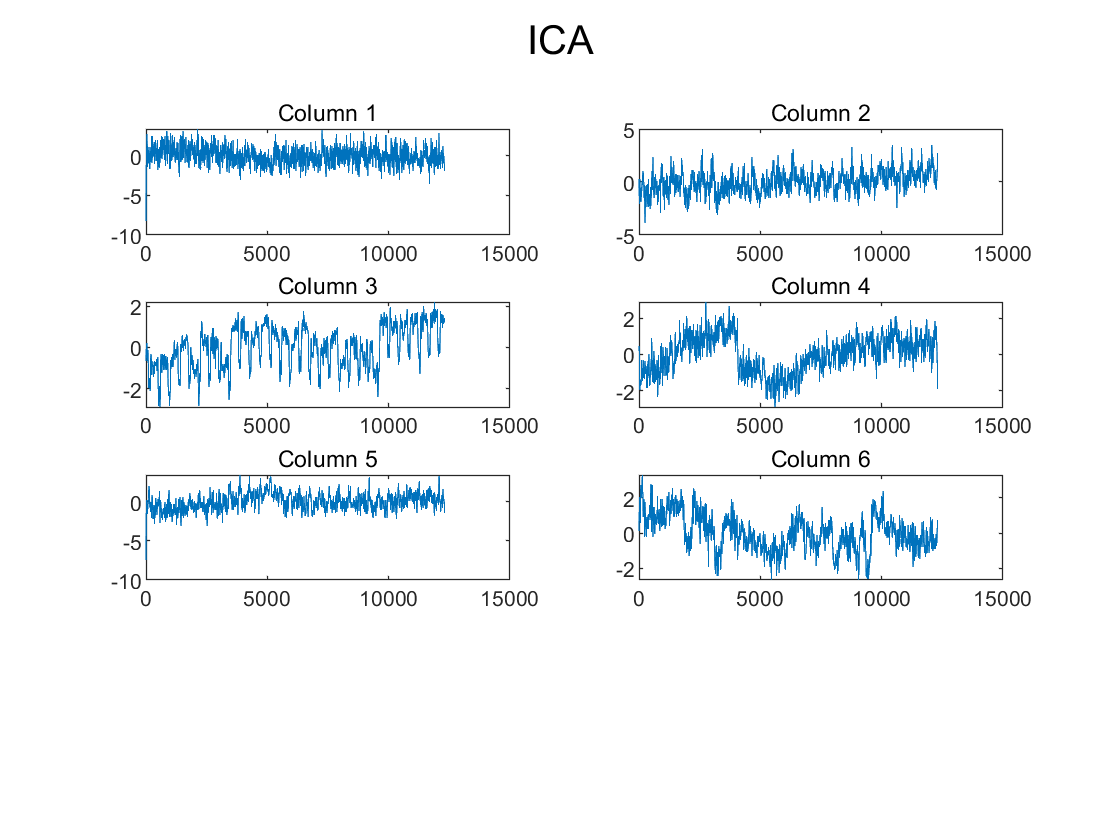

% 分解得到的 S 表示独立成分
% 绘制七个子图
for i = 1:r
    subplot(4, 2, i);  % 创建7行1列的子图，i指定当前子图位置
    plot(S(i,:));  % 绘制第i列数据
    title(['Column ' num2str(i)]);  % 设置每个子图的标题
end
sgtitle("ICA");

PCA测试

F = I(commu_4,win_train)';
F_std = zscore(F); % 标准化

% 2. 主成分分析
[coeff, score, latent, ~, explained] = pca(F_std); % PCA 分解
% coeff: 载荷矩阵, score: 主成分得分, latent: 特征值, explained: 贡献率
% 3. 分析主成分
cum_explained = cumsum(explained); % 累计贡献率
disp('累计贡献率:');

累计贡献率:


disp(cum_explained);

   81.7670
   97.7199
   99.3376
   99.7907
   99.9994
  100.0000



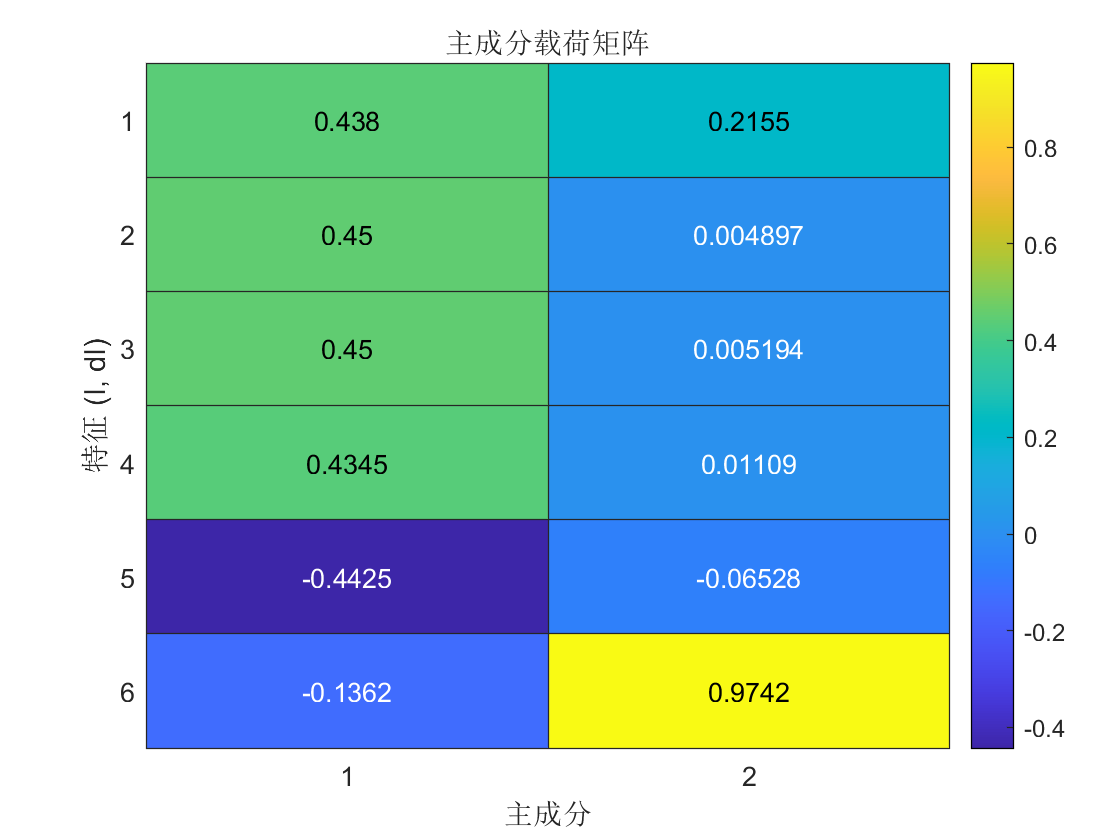

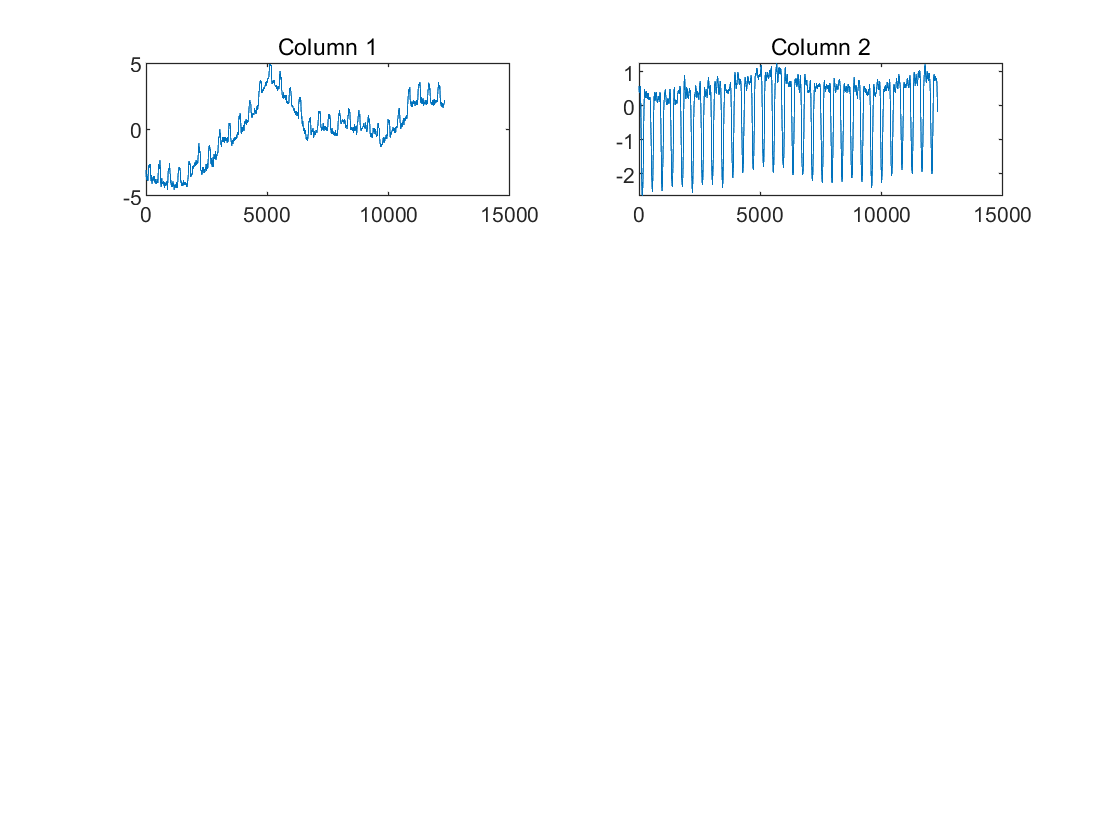


% 选择主要主成分（贡献率达到 95%）
num_components = find(cum_explained >= 95, 1);
% 4. 可视化载荷矩阵
figure;
heatmap(coeff(:, 1:num_components), 'Colormap', parula, ...
    'Title', '主成分载荷矩阵', 'XLabel', '主成分', 'YLabel', '特征 (I, dI)');
figure;

% 绘制七个子图
for i = 1:num_components
    subplot(4, 2, i);  % 创建7行1列的子图，i指定当前子图位置
    plot(score(:, i));  % 绘制第i列数据
    title(['Column ' num2str(i)]);  % 设置每个子图的标题
end

% 使用 linkaxis 函数链接所有子图的坐标轴
linkaxes(findobj(gcf, 'Type', 'axes'), 'x');  % 'xy' 表示链接x轴和y轴